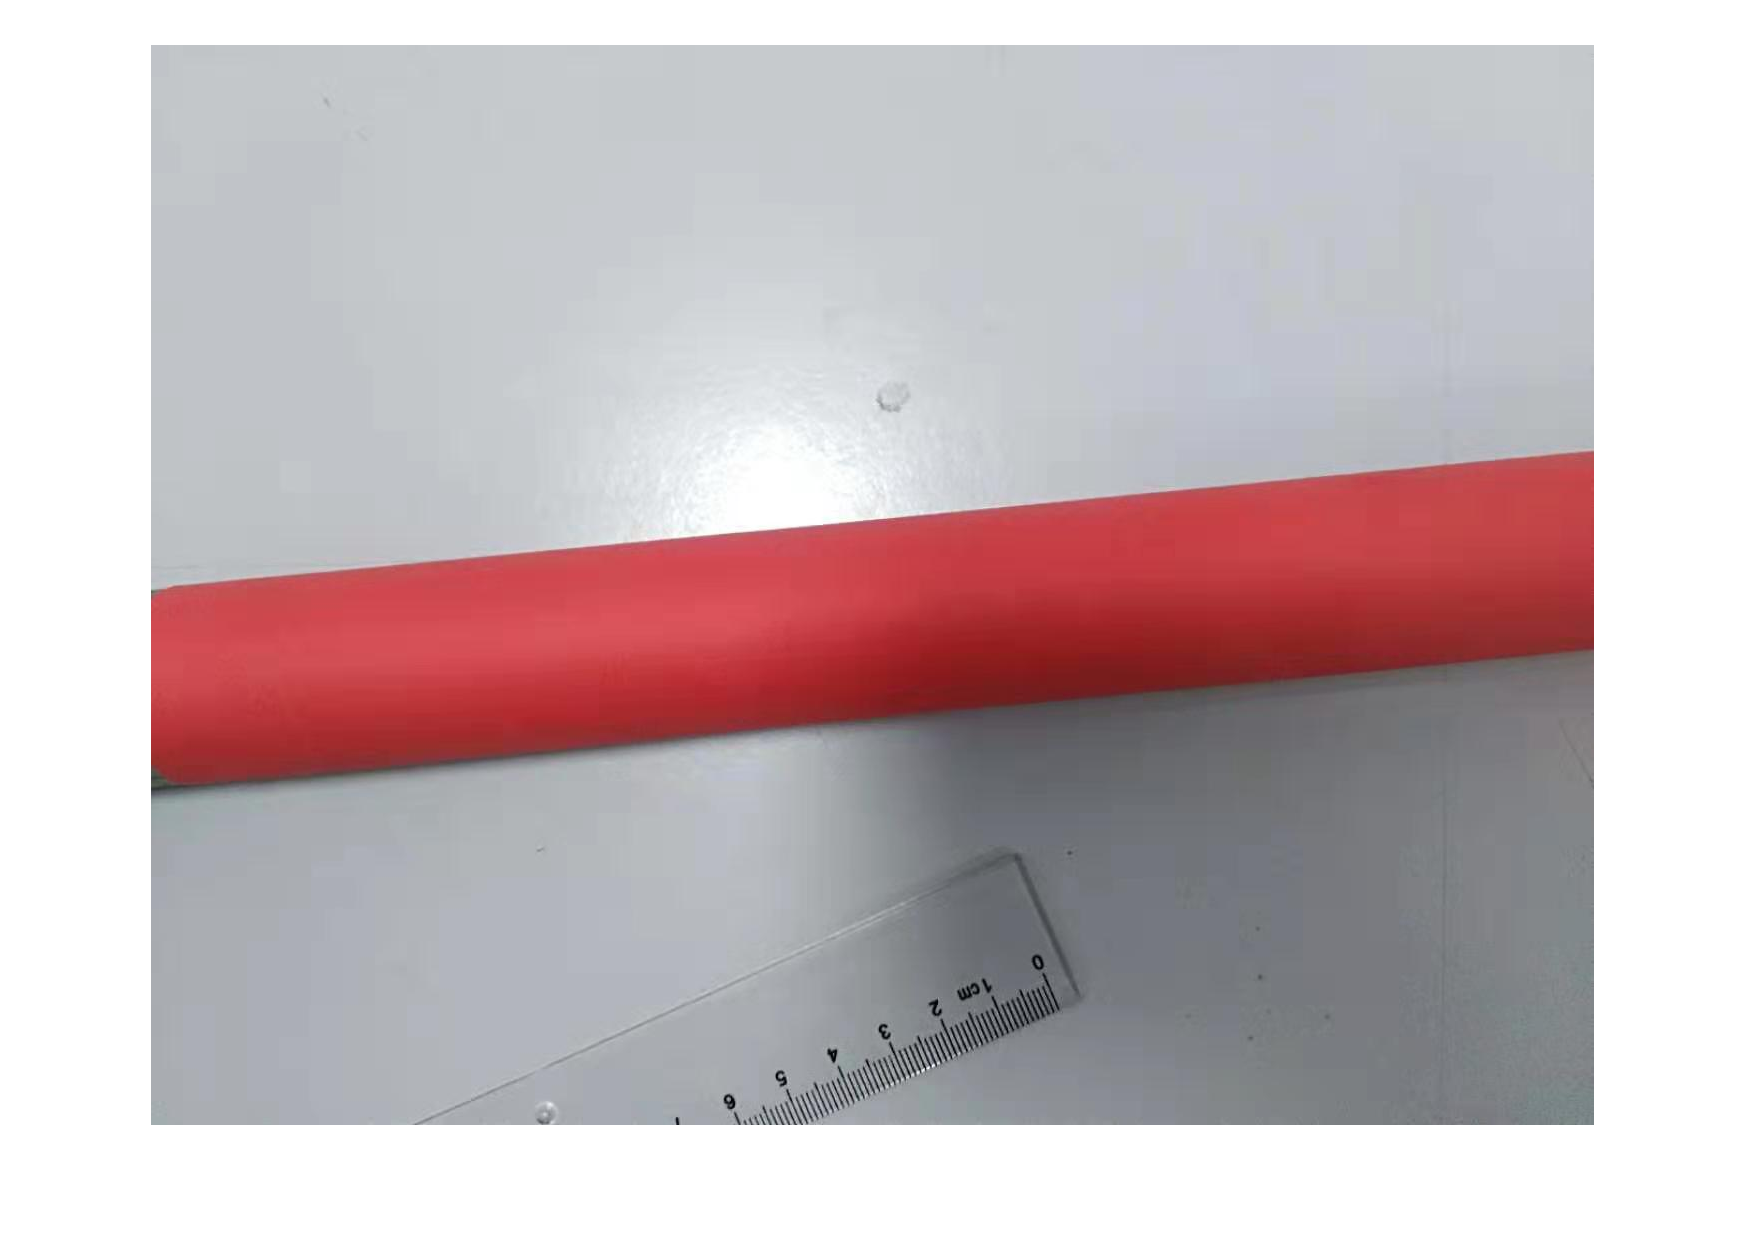

img = imread("./data/3.jpg");
img = im2double(img);
width=size(img,2);
height=size(img,1);

figure, imshow(img);

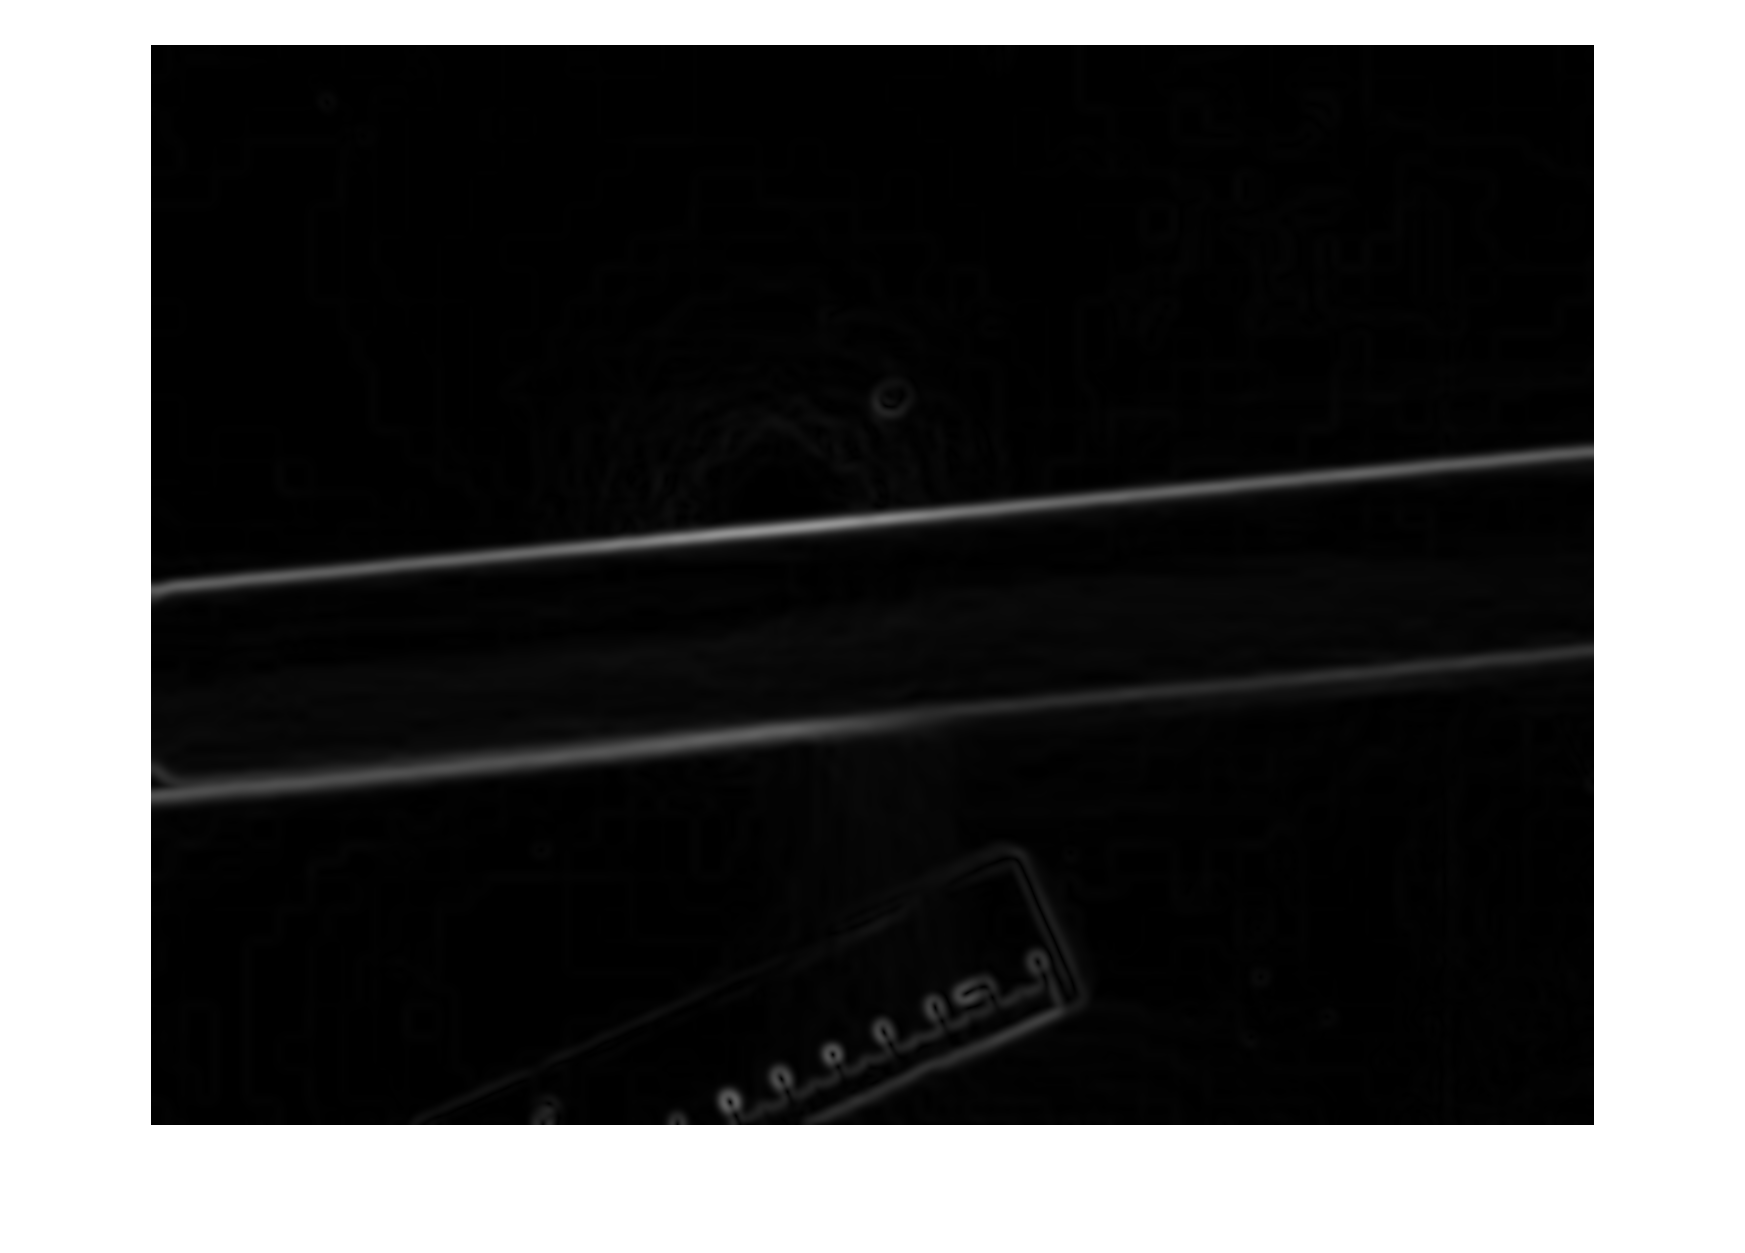

edges = compute_edges(img,5);

figure, imshow(edges);

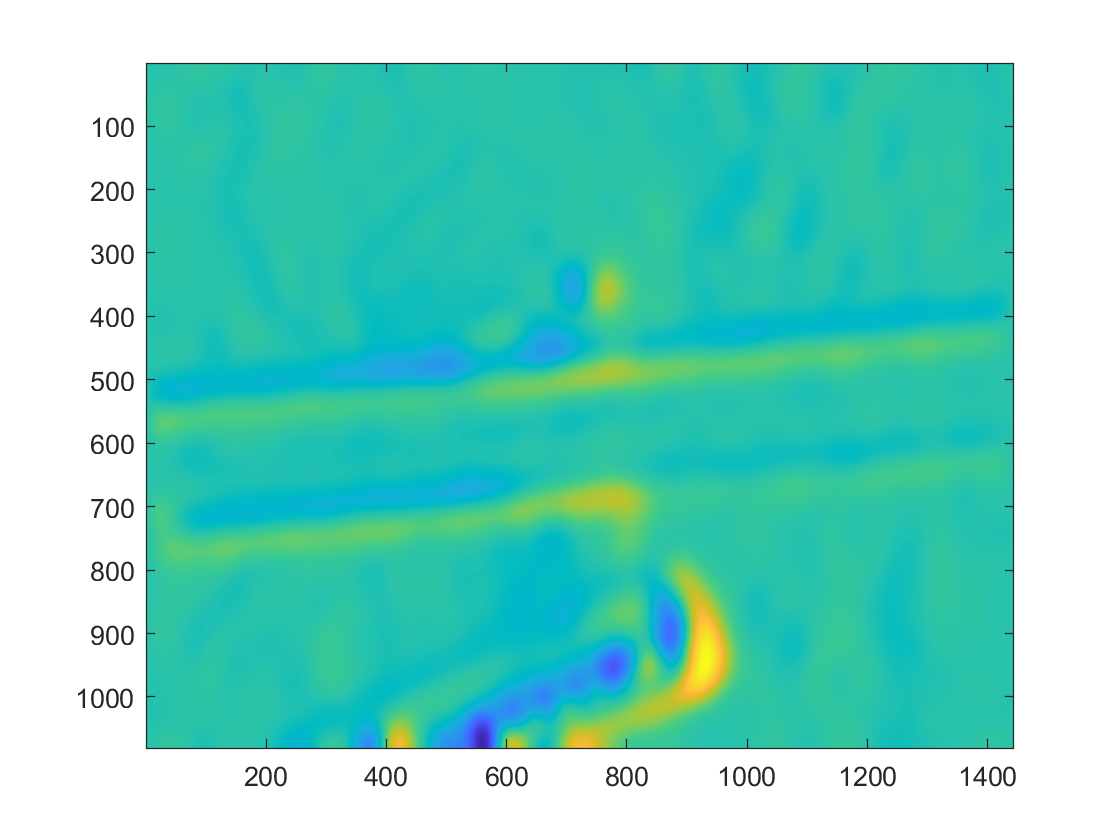

grad = compute_grad(edges,25);

figure, imagesc(grad(:,:,1));

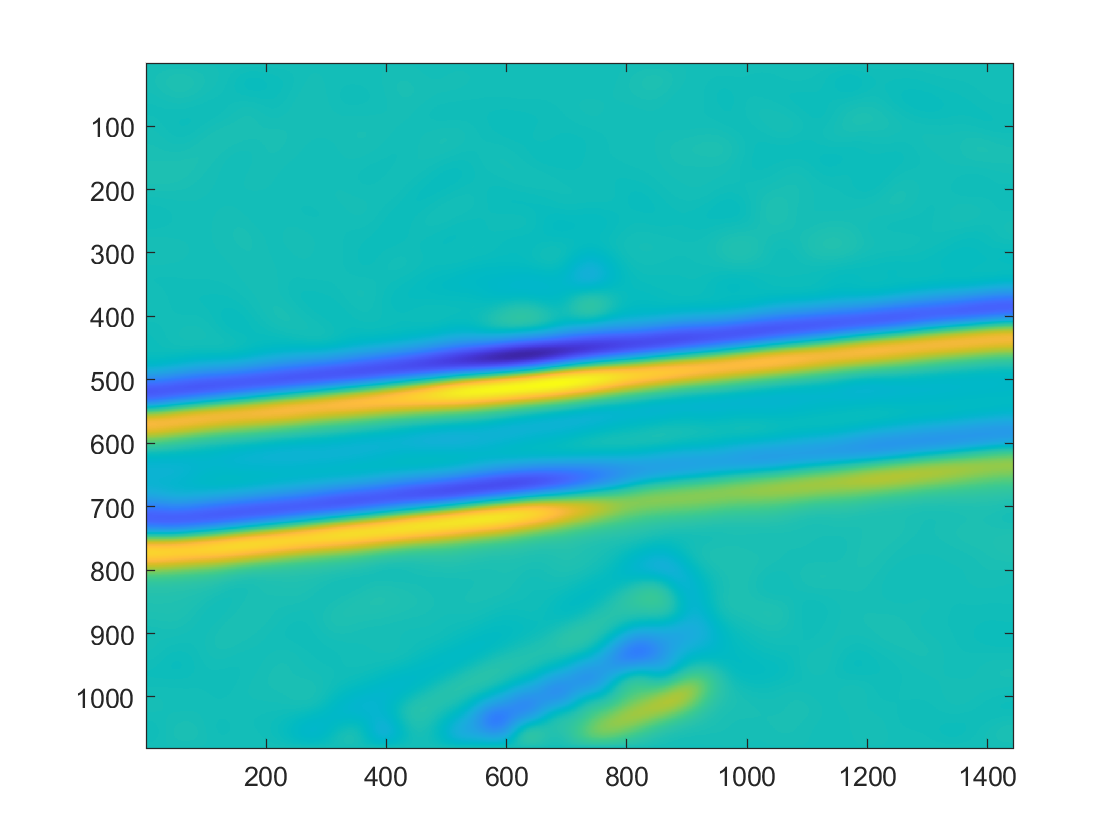

figure, imagesc(grad(:,:,2));

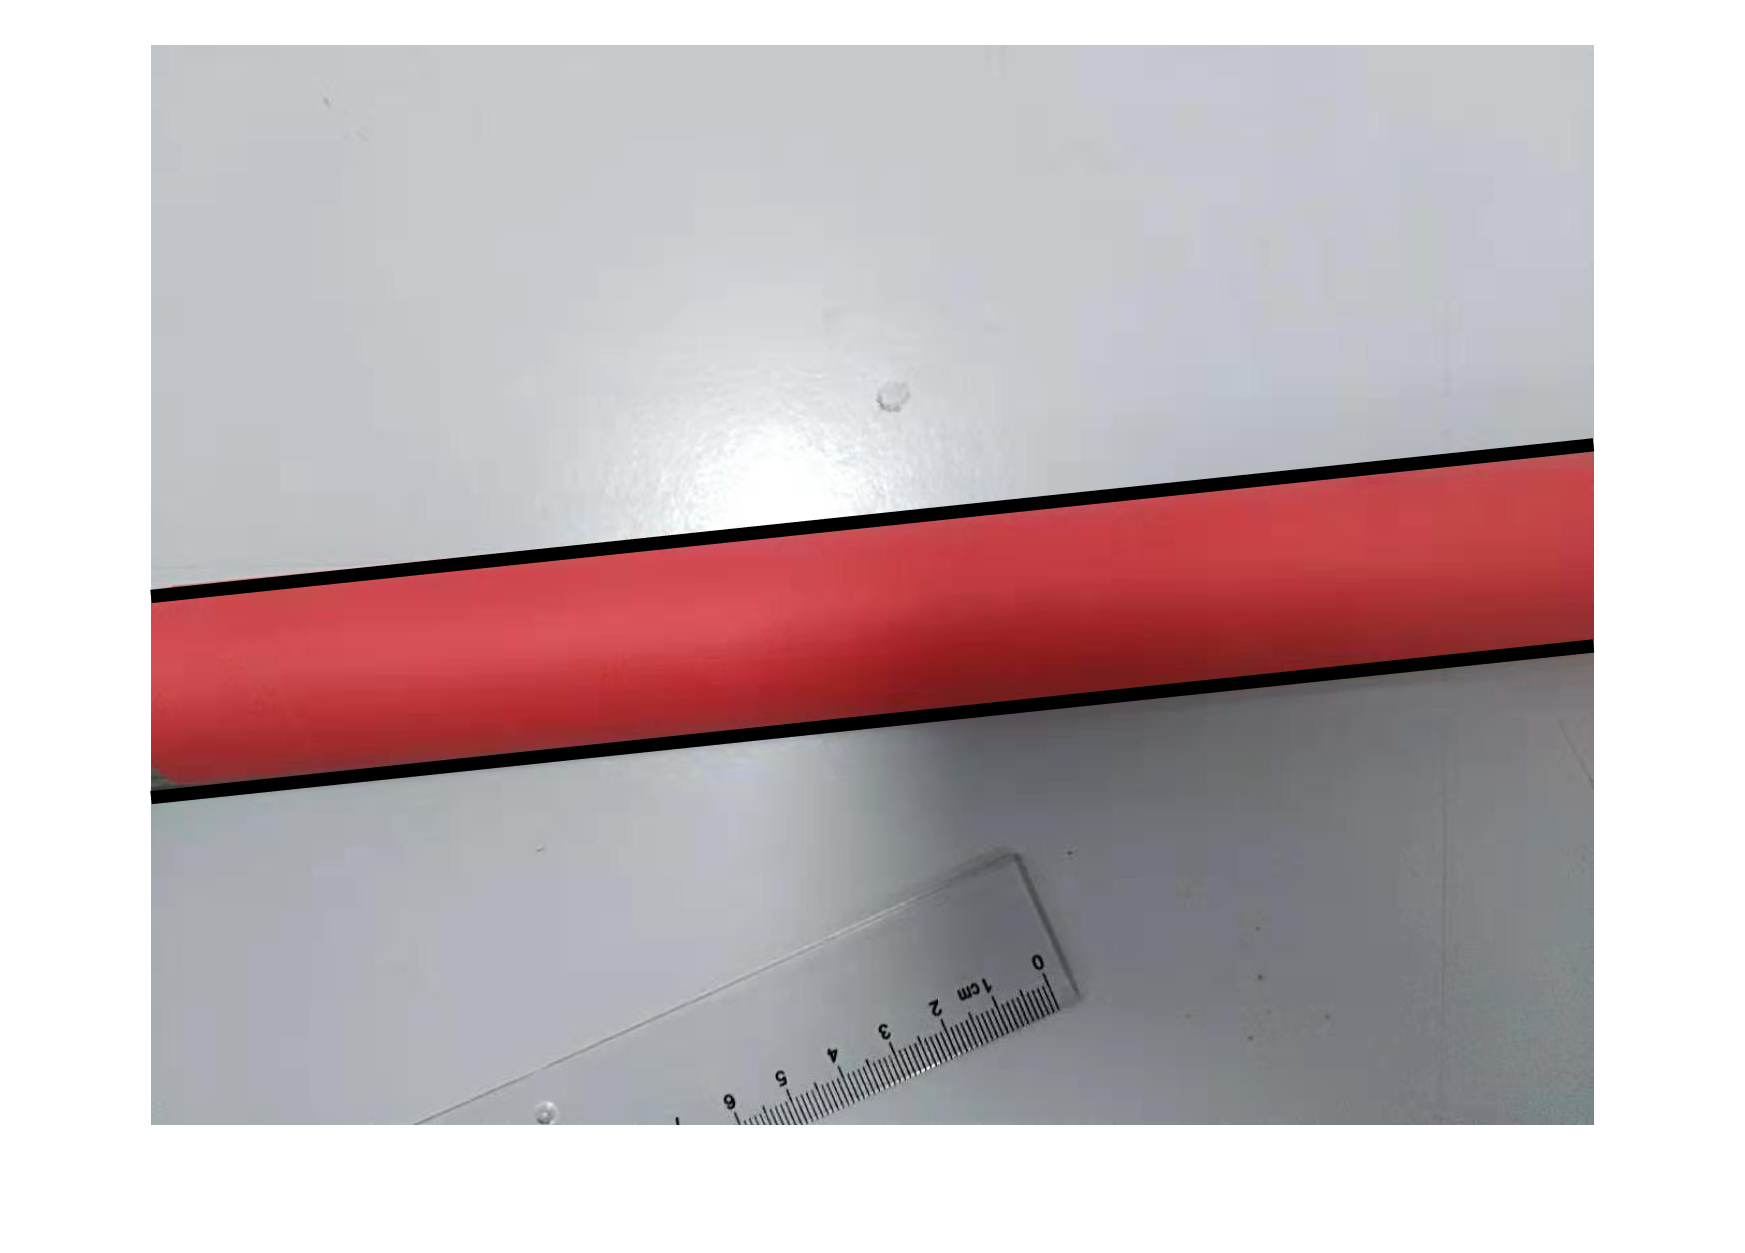

[theta1, rho1, theta2, rho2] = find_parallel(edges,0.03);

figure; imshow(img), hold on
plot_line(width,height,theta1,rho1);
plot_line(width,height,theta2,rho2);